#### X.2.1 Time domain tuning

Start with some regular exercises to measure the stiffness

Kp: with increasing force it has more oscillation to go back, with slow perturbbations, the stiffness increases more and more. With fast and light perturbations it quickly shoots back to the setpoint. It always quickly gains momentum to move back.

Kd: on the other hand causes damping of fast movements in that it reduces the motion and damps the actual force that you try to apply. You don't see it returning however, that is only caused by the proportional gain that returns the system to a setpoint.

#### X.2.2 FRF measurement

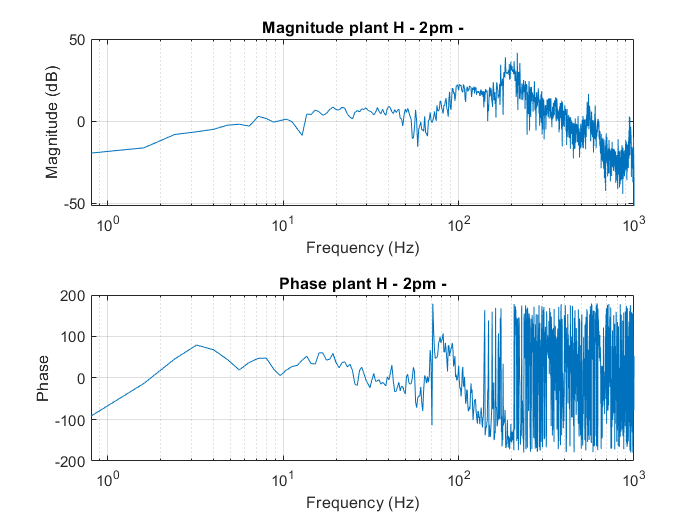

% How does this actually work?
% SPERTE_Measure_And_Collect(6,2,1000,"Reference_model_Control_Engineering",1)

% Adjust parameters 
Fs = 2000;
Ts = 1/Fs;

% Adjustable parameters
res = 0.8; % in Herz
nfft = Fs / res;
noverlap = nfft/2;
% Import all signals
u_mm = simout_u.signals.values;
d_mm = simout_disturb.signals.values;
e_mm = simout_error.signals.values;

% Let's make the two-point estimate and the three point estimate
[Sens_2p, f_Sens_2p] = tfestimate(d_mm,u_mm,hann(nfft),noverlap,nfft,Fs);
f_Sens_2p = f_Sens_2p;

figure;
t1 = tiledlayout(3,1);
nexttile
semilogx(f_Sens_2p, 20*log10(abs(Sens_2p)));
title("Magnitude sensitivity closed loop FRF")
xlabel("Frequency (Hz)")
ylabel("Magnitude (dB)")
grid on
nexttile 
semilogx(f_Sens_2p, angle(Sens_2p)*180/pi);
title("Phase sensitivity closed loop FRF")
xlabel("Frequency (Hz)")
ylabel("Phase")
grid on
nexttile
[coh_2p, f_coh_2p] = mscohere(d_mm, u_mm,hann(nfft),noverlap,nfft,Fs);
semilogx(1./f_coh_2p, coh_2p)
title("Coherence process sensitivity closed loop FRF")
xlabel("Frequency (Hz)")
ylabel("Coherence")
grid on
% Now calculate the 2-point open loop 
L_2p = (1-Sens_2p)./Sens_2p; % Open loop

figure;
t2 = tiledlayout(2,1);
nexttile
semilogx(f_Sens_2p, 20*log10(abs(L_2p)));
title("Magnitude open loop - 2pm - FRF")
xlabel("Frequency (Hz)")
ylabel("Magnitude (dB)")
grid on
nexttile 
semilogx(f_Sens_2p, angle(L_2p)*180/pi);
title("Phase open loop - 2pm - FRF")
xlabel("Frequency (Hz)")
ylabel("Phase")
grid on

% The controller can be measured from the error and u, so
control_mm = simout_controller.signals.values;
[C_2p, f_C_2p] = tfestimate(e_mm, control_mm, hann(nfft), noverlap, nfft,Fs);

H_2p = (C_2p).*L_2p;

figure;
t3 = tiledlayout(2,1);
nexttile
semilogx(f_Sens_2p, 20*log10(abs(H_2p)));
title("Magnitude plant H - 2pm - FRF")
xlabel("Frequency (Hz)")
ylabel("Magnitude (dB)")
grid on
nexttile 
semilogx(f_Sens_2p, angle(H_2p)*180/pi);
title("Phase plant H - 2pm - FRF")
xlabel("Frequency (Hz)")
ylabel("Phase")
grid on
% Now for the three point measurement
[PSens_3p, f_PSens_3p] = tfestimate(d_mm,e_mm,hann(nfft),noverlap,nfft, Fs);
f_PSens_3p = f_PSens_3p;

figure;
t4 = tiledlayout(3,1);
nexttile
semilogx(f_PSens_3p, 20*log10(abs(PSens_3p)));
title("Magnitude PSensitivity - 3pm - FRF")
xlabel("Frequency (Hz)")
ylabel("Magnitude (dB)")
grid on
nexttile 
semilogx(f_PSens_3p, angle(PSens_3p)*180/pi);
title("Phase PSensitivity - 3pm - FRF")
xlabel("Frequency (Hz)")
ylabel("Phase")
grid on
nexttile
[coh_3p, f_coh_3p] = mscohere(d_mm, e_mm,hann(nfft),noverlap,nfft,Fs);
semilogx(f_coh_2p, coh_2p)
title("Coherence process sensitivity closed loop FRF")
xlabel("Frequency (Hz)")
ylabel("Coherence")
grid on
% saveas(figure, sprintf('Figure_%d.png'));
% Now let's directly calculate the plant H

H_3p = -PSens_3p ./ Sens_2p;

figure;
t5 = tiledlayout(2,1);
nexttile
semilogx(f_PSens_3p, 20*log10(abs(H_3p)));
title("Magnitude plant H - 3pm - FRF")
xlabel("Frequency (Hz)")
ylabel("Magnitude (dB)")
grid on
nexttile 
semilogx(f_PSens_3p, angle(H_3p)*180/pi);
title("Phase plant H - 3pm - FRF")
xlabel("Frequency (Hz)")
ylabel("Phase")
grid on
figure; % probably something wrong?
t6 = tiledlayout(2,1);
nexttile
semilogx(f_Sens_2p, 20*log10(abs(H_2p)));
title("Magnitude plant H - 2pm -")
xlabel("Frequency (Hz)")
ylabel("Magnitude (dB)")
grid on
nexttile 
semilogx(f_Sens_2p, angle(H_2p)*180/pi);
title("Phase plant H - 2pm -")
xlabel("Frequency (Hz)")
ylabel("Phase")
grid on

#### If IMAGES export

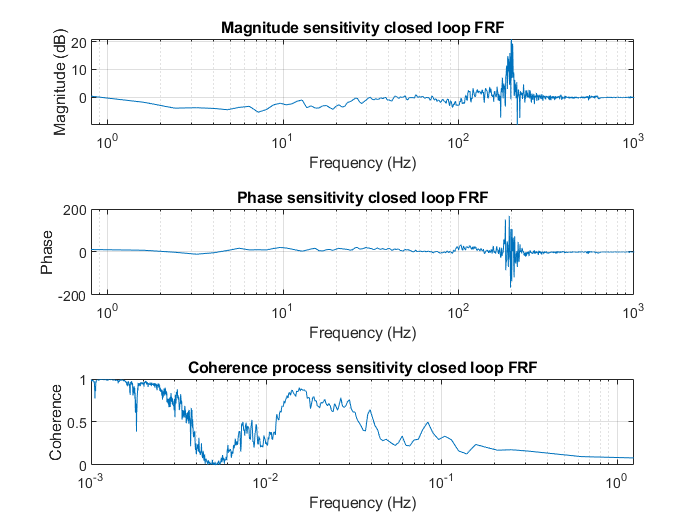

% % % Export all results
exportgraphics(t1, 'Sensitivity_FRF_2pm.png', 'Resolution', 300);  % Or use .pdf for vector graphics

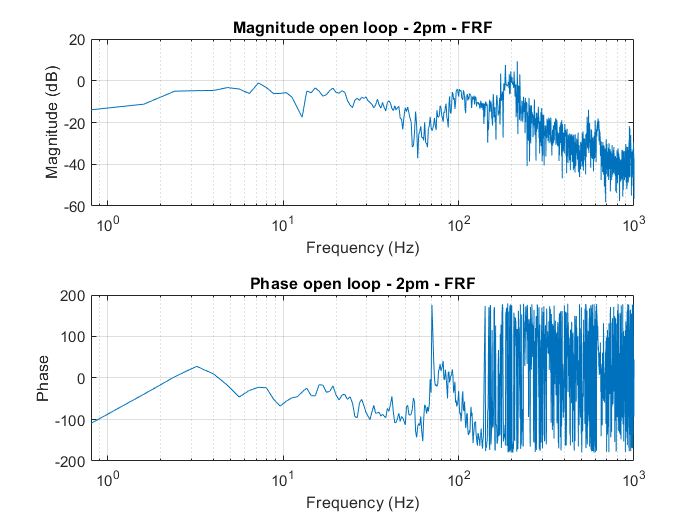

exportgraphics(t2, 'Openloop_FRF_2pm.png', 'Resolution', 300);  % Or use .pdf for vector graphics

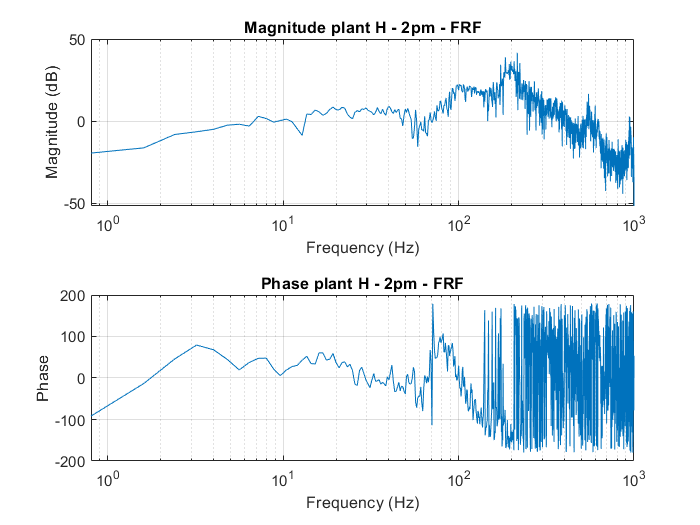

exportgraphics(t3, 'Plant_FRF_2pm.png', 'Resolution', 300);  % Or use .pdf for vector graphics

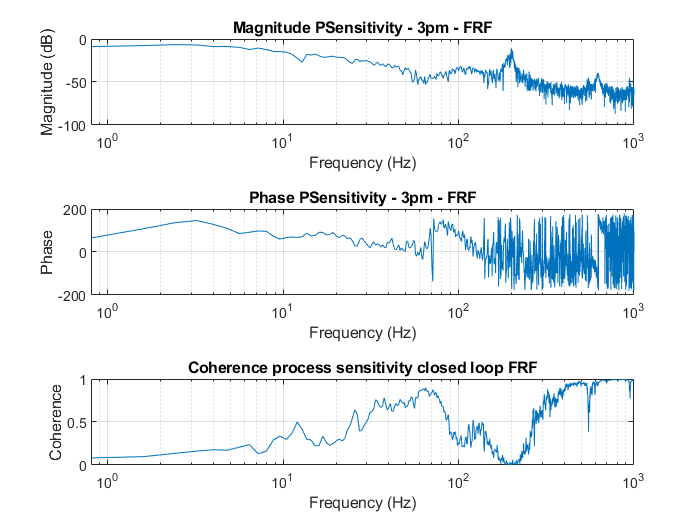

exportgraphics(t4, 'PSens_FRF_3pm.png', 'Resolution', 300);  % Or use .pdf for vector graphics

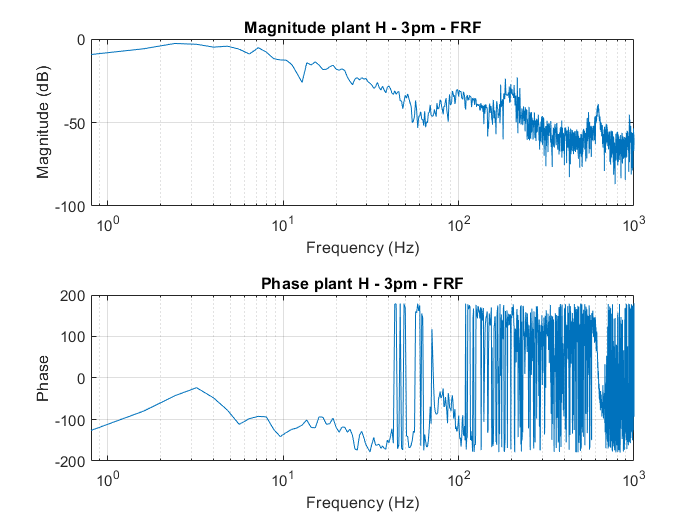

exportgraphics(t5, 'Plant_FRF_3pm.png', 'Resolution', 300);  % Or use .pdf for vector graphics

Jogmode error